Porównajmy dokładność całki obliczanej metodą trapezów i metodą Simpsona (parabol).

clear all;
close all;
%zwybór funkcji, z której będzie obliczana całka
syms f(x)
f(x)=x^6+3*x^4-2*x

$$f(x) = x^{6}+3\,x^{4}-2\,x$$



%Uruchom w domyślnym przedziale
deafVal=true;
%umieszczanie wartosci calki na wykresach
intVis=true;


if deafVal==true
    if strcmp(string(char(f(x))),"sin(x)")
        a=0
        b=10
    end
    if strcmp(string(char(f(x))),"x^3 - 2*x^2 - 5*x - 3")
        a=-3
        b=4
    end
    if strcmp(string(char(f(x))),"3*x^4 - 2*x + x^6")
        a=-1
        b=1
    end
    if strcmp(string(char(f(x))),"3*x + x^2 - 5")
        a=-3
        b=2
    end
    if strcmp(string(char(f(x))),"exp(x)")
        a=1
        b=5
    end        
else
    a=input("Podaj lewy kraniec przedzialu:")
    b=input("Podaj prawy kraniec przedzialu:")
    if a>=b
        display("Prawy kraniec przedziału musi być liczbą większą od lewego krańca.")
        return
    end
end

a = -1

b = 1


calka_dokladna=double(int(f,a,b))

calka_dokladna = 1.4857

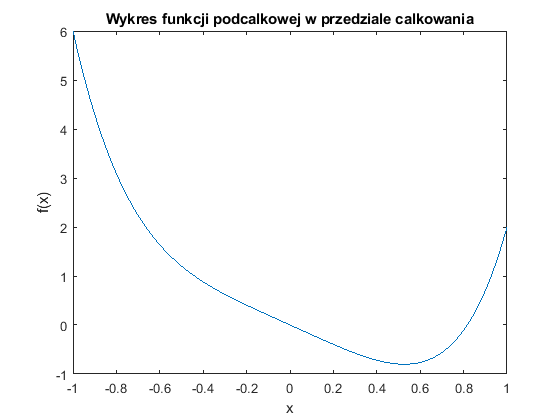




Q=2;
x1=linspace(a,b,abs(b-a)*100);
[min_f,min_i]=min(double(f(x1)));
[max_f,max_i]=max(double(f(x1)));
xmin=a+(min_i-1)/100;
xmax=a+(max_i-1)/100;

figure()
plot(x1,f(x1))
title 'Wykres funkcji podcalkowej w przedziale calkowania'
xlabel 'x'
ylabel 'f(x)'

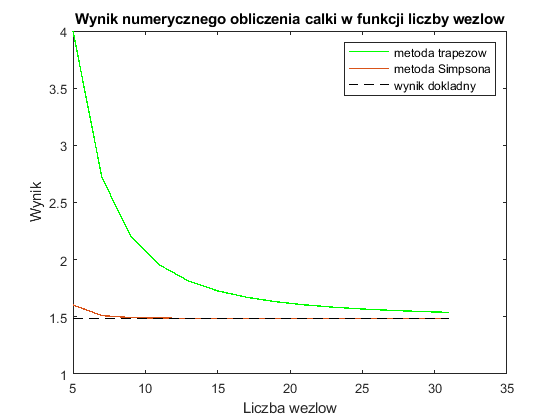


N=15;
x2=Q:N;
x2=x2*2;
for k=x2
    d_podprze=2*(b-a)/k;
    pkt_l=(a:d_podprze:b-d_podprze);
    pkt_r=(a+d_podprze:d_podprze:b);
    pkt_2j=(a+d_podprze/2:d_podprze:b-d_podprze/2);
    calka_trapez(k/2-Q+1)=sum(double(f(pkt_l)+f(pkt_r))/2)*d_podprze;
    calka_simpson(k/2-Q+1)=sum(double(f(pkt_l)+4*f(pkt_2j)+f(pkt_r))/6)*d_podprze;
    blad_trapez(k/2-Q+1)=abs((calka_trapez(k/2-Q+1)-calka_dokladna)/calka_dokladna);
    blad_simpson(k/2-Q+1)=abs((calka_simpson(k/2-Q+1)-calka_dokladna)/calka_dokladna);
end
figure()
plot(x2+1,calka_trapez,'g',x2+1,calka_simpson, x2+1, linspace(calka_dokladna,calka_dokladna,N-Q+1),'k--', 'lineWidth', 1)
title 'Wynik numerycznego obliczenia calki w funkcji liczby wezlow'
xlabel 'Liczba wezlow'
ylabel 'Wynik'
legend(' metoda trapezow', ' metoda Simpsona', ' wynik dokladny')

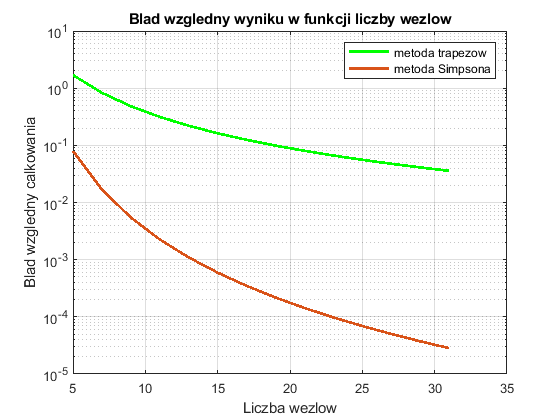

figure()
semilogy(x2+1,blad_trapez,'g',x2+1, blad_simpson, 'lineWidth', 2)
title 'Blad wzgledny wyniku w funkcji liczby wezlow'
xlabel 'Liczba wezlow'
ylabel 'Blad wzgledny calkowania'
legend(' metoda trapezow', ' metoda Simpsona')
grid on